# An explorational test method for learning vehicle control system robustness against sensor noise and MITM attack

### Test environment

The environment is a 14DOF passenger car with different sub components (e.g. Driveline, Engine (SI), vehicle body).

The vehicle is controlled with simulated digital ECUs. The ECUs are fed with sensor signals sampled from the simulation at every 5msec. And controls the vehicle dynamics by actuators with commands at each 5msec. The sensor signals and actuator commands are converted back and forth to fixed point numbers as they were embedded ito CAN frames.

The model used has a test "device" which introduce noise into the wheel speed sensor digital data flow: Each captured "true" wheel speed value is followed by a fake wheel speed sample.

### Vision

The proposed test method explores the stability of the investigated control system, the quality of its sensor signal conditioning algarithms and the its ability to learn external interventions. The proposed method shall find the worst ECU performance by keeping its base operation alive. The test schedule is learnt and can be repetatively used later to evaluate the control algorithm as wel as its infrasructure like signal conditioning and security protection.

### Method

At each controller action phase (at 5 msec sampling) the controller decides if it accepts the signal or refuse its use and stay with the previous state. If the controller accept the sensor value it can be either the true sample or "close" to the true value. Then the expected controller behavior is close to the undisturbed operation i.e. its performance is close to the specification. Similarly if the controller rejects the sensor value and use only the last accepted sample, its performance shall be acceptable. Remember only every second signal is tampered.

### Result

The result shall be a trained actor (test "device") which can be used in  MIL, SIL and HIL to evaluate the controller performance.

## Preparation

addpath("Config")
addpath("Driveline")
addpath("SI")
addpath("Vehicle")

mdl = "PassCarModel_RL_config";
open_system(mdl);

% Fuzzing noise offset in the interval of 
FO_max = 50;
FO_min = 0;

% Fuzzing noise variation in the range of 
FR_max = 0;
FR_min = 0;

% Reward deceleration component
DecelR = 0;
% Reward wheel speed deviation
ODevR = 0;

% agent and environment interaction time periods
Ts = 0.01;

% total episode time
Tf = 20;

The test device is a Reinforcement Learning actor. The actor

- gets its obeservation from the environment as 4 wheel speeds and the vehicle longitudinal speed and

- issue its actions as noises on the wheel speed signals.

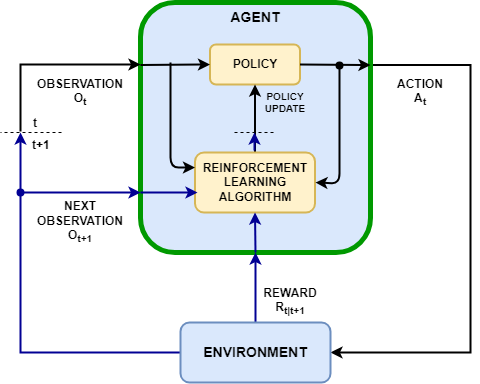

The agent contains two components: a policy and a learning algorithm.

- The policy is a mapping from the current environment observation (wheel speeds and vehicle speed) to a probability distribution of the actions (noise to be injected to the wheel speed signals) to be taken. Within an agent, the policy ("test device") is implemented by a function approximator with tunable parameters and a specific approximation model, such as a deep neural network.

- The learning algorithm continuously updates the policy learnable parameters based on the actions, observations, and rewards. The goal of the learning algorithm is to find an optimal policy that maximizes the expected discounted cumulative long-term reward received during the task.

action = [-1 -0.8 -0.6 -0.4 -0.2 0 0.2 0.4 0.6 0.8 1];
actionInfo = rlFiniteSetSpec({action action action action});
obsInfo = rlNumericSpec([5 1]);

env = rlSimulinkEnv(mdl, mdl + "/Agent/RL Agent", obsInfo, actionInfo, 'UseFastRestart', 'on');

env.ResetFcn = @(in)MyResetFunction(in);

The RL agent is a Soft Actor Critic agent

new_training = true;
if new_training
    previousRngState = rng(0,"twister");
    rng(0,"twister");

    agent = rlSACAgent(obsInfo, actionInfo);
    
    agent.UseExplorationPolicy = true;
    
    agent.AgentOptions.ExperienceBufferLength = 1e6;
    agent.AgentOptions.SampleTime = Ts;

    agent.AgentOptions.ActorOptimizerOptions.Algorithm = "adam";
    agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-4;
    agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
    
    for ct = 1:2
        agent.AgentOptions.CriticOptimizerOptions(ct).Algorithm = "adam";
        agent.AgentOptions.CriticOptimizerOptions(ct).LearnRate = 5e-4;
        agent.AgentOptions.CriticOptimizerOptions(ct).GradientThreshold = 1;
    end
    agent.AgentOptions.MiniBatchSize = 64;
else
    load("d:\Test2\PassCarModel\savedAgents\SAC_PassCarModelX_RL_norm_offset_disc_4w_lat\Agent2800.mat");
    agent = saved_agent;
end

The agent is only trained during the ABS braking. Therefore the first part of the maneouvre is not needed, so save the operation point of the start of ABS braking.

% save the operation point at the beginning of ABS braking
simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn,"SaveFinalState","on");
simIn = setModelParameter(simIn,"SaveOperatingPoint","on");
simIn = setModelParameter(simIn,"StopTime","11.7");
simIn = setBlockParameter(simIn, mdl + "/Agent/StoppingCondition", Value="-100");
out = sim(simIn);

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 1.1808s


Input size error
	Error in 'PassCarModel_RL_config/Agent/Policy/MATLAB Function' (line 15)
		error('Input size error');

pcmOP = out.xFinal;
save("PassCarModel_Final_OperationPoint.mat", "pcmOP");
%setBlockParameter(simIn, mdl + "/StoppingCondition", Value="0.1");

### Training

The training is using an emergency braking in a curve. The return of an actoin (noise) is the decreased capability of keeping the turning while decelerating as mumch as possible. The episode reward is the sum of returns during the braking.

%function dataToLog = logAgentLearnData(data)
    % This function is executed after completion
    % of the agent's learning subroutine.
%    dataToLog.ActorLoss = data.ActorLoss;
%    dataToLog.CriticLoss = data.CriticLoss;
%end

training = true;
if training
    maxepisodes = 5000;
    maxsteps = ceil(Tf/Ts);
    trainOpts = rlTrainingOptions(...
        MaxEpisodes=maxepisodes,...
        MaxStepsPerEpisode=maxsteps,...
        ScoreAveragingWindowLength=5,...
        Verbose=false,...
        Plots="training-progress",...
        StopTrainingCriteria="EvaluationStatistic",...
        StopTrainingValue=10,...
        SaveAgentCriteria="EvaluationStatistic",...
        SaveAgentValue=-12,...
        SimulationStorageType="file",...
        SaveSimulationDirectory="envSimData");
    
    evaluator = rlEvaluator(NumEpisodes=1,EvaluationFrequency=10);
       
    %logger = rlDataLogger();
    %logger.LoggingOptions.LoggingDirectory = "rlDataLog";
    %logger.AgentLearnFinishedFcn = @logAgentLearnData;
    
    % Train the agent.
    %trainingResults = train(agent, env, trainOpts, Evaluator=evaluator, Logger=logger);
    trainingResults = train(agent, env, trainOpts, Evaluator=evaluator);
    
    save('TrainingResult.mat', "trainingResults");
    
    simOptions = rlSimulationOptions(MaxSteps=500);
    experience = sim(env, agent, simOptions);
    save('experience.mat', "experience");

    rng(previousRngState);
end

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 1.5207s


Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

Error in internal_reshape (line 8)
    x = reshape(x,varargin{:});

Error in deep.internal.recording.operations.ReshapeOp/forward (

### Training statistics

The following code assumes that the training results in saved agent. If so it displays the training statistics.

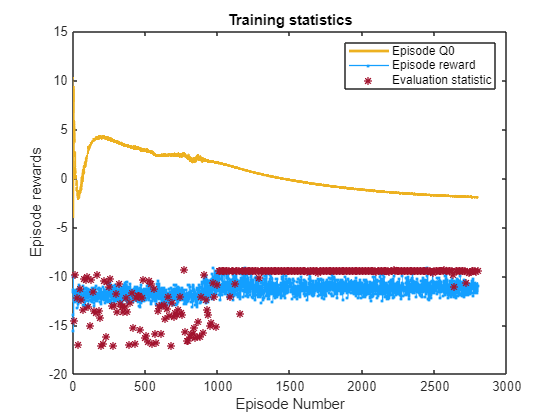

load("d:\Test2\PassCarModel\savedAgents\SAC_PassCarModelX_RL_norm_offset_disc_4w_lat\Agent2800.mat");
%load("d:\Test2\PassCarModel\savedAgents\Agent2490.mat");
x = 1:2800;

figure;

plot(x, savedAgentResult.EpisodeQ0, 'DisplayName','Episode Q0','LineWidth',2, ...
    'Color',[0.929411764705882 0.694117647058824 0.125490196078431]);
hold on;
 
plot(x, savedAgentResult.EpisodeReward, 'DisplayName','Episode reward','Marker','.','LineWidth',1,...
    'Color',[0.0745098039215686 0.623529411764706 1]);
 
scatter(x(~isnan(savedAgentResult.EvaluationStatistic)), ...
    savedAgentResult.EvaluationStatistic(~isnan(savedAgentResult.EvaluationStatistic)), 'DisplayName','Evaluation statistic',...
    'MarkerEdgeColor',[0.635294117647059 0.0784313725490196 0.184313725490196],...
    'LineWidth',1,...
    'Marker','*');
 
hold off; 
% Labels and legend
xlabel('Episode Number');
ylabel('Episode rewards');
title('Training statistics');
legend('Episode Q0', 'Episode reward', 'Evaluation statistic');

### Evaluation

The "best" performing parameterset of the actor has been reached not at the end of the training.

if ~exist('pcmOP', 'var')
    load("PassCarModel_Final_OperationPoint.mat", "pcmOP");
end
load("d:\Test2\PassCarModel\savedAgents\SAC_PassCarModelX_RL_norm_offset_disc_4w_lat\Agent2750.mat");
agent = saved_agent;

simIn = Simulink.SimulationInput(mdl);
simIn = simIn.setInitialState(pcmOP);
simIn = setBlockParameter(simIn, mdl + "/Agent/Policy/Fuzzing", Value="0");
out = sim(simIn);

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 1.3504s


simOptions = rlSimulationOptions(MaxSteps=500);
agent = saved_agent;
agent.UseExplorationPolicy = false;
experience = sim(env, agent, simOptions);

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 1.269s


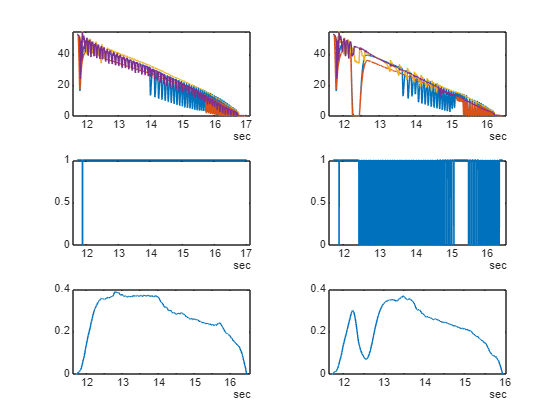


figure;
tiledlayout(3, 2);

nexttile;
o = timeseries2timetable(out(1).logsout.getElement("Omega").Values);
plot(o.Time, o{:,1});

nexttile;
o = timeseries2timetable(experience.SimulationInfo(1).logsout.getElement("Omega").Values);
plot(o.Time, o{:,1});

nexttile;
tt = timeseries2timetable(out.logsout.getElement("RearAxle_WS_check").Values);
v_tt = timeseries2timetable(out.logsout.getElement("VehSpeed_WS_Check").Values);
plot(tt.Time, tt{:,1});
plot(v_tt.Time, v_tt{:,1});

nexttile;
tt = timeseries2timetable(experience.SimulationInfo(1).logsout.getElement("RearAxle_WS_check").Values);
v_tt = timeseries2timetable(experience.SimulationInfo(1).logsout.getElement("VehSpeed_WS_Check").Values);
plot(tt.Time, tt{:,1});
plot(v_tt.Time, v_tt{:,1});

nexttile;
ala = timeseries2timetable(out.logsout.getElement("AvgLatAcc").Values);
plot(ala.Time, ala{:,1});
ylim([0 0.4]);

nexttile;
ala = timeseries2timetable(experience.SimulationInfo(1).logsout.getElement("AvgLatAcc").Values);
plot(ala.Time, ala{:,1});
ylim([0 0.4]);

hold off;

**First row**: the first graph shows a simulated ABS braking in a curve with showing the wheel speeds. The controller maximize the utilization of the adhesion in order to efficiently braking the vehicle and keeping it in the road. The second graph shows a "disturbed" operation in which one of the front wheel is blocking, which results in failure in the maneouvre. 

**Second row**: the graphs show the results of the signal preprocessing part of the ABS algorithm. In the shaded area the algorithm rejects the "disturbed" signals. The test environment generated a "noise" for the first half of the ABS braking that braked the proper ABS behaviour, however in the second half the generated noise was efficiently removed and the processing of the true signal sampes resulted in proper operation.

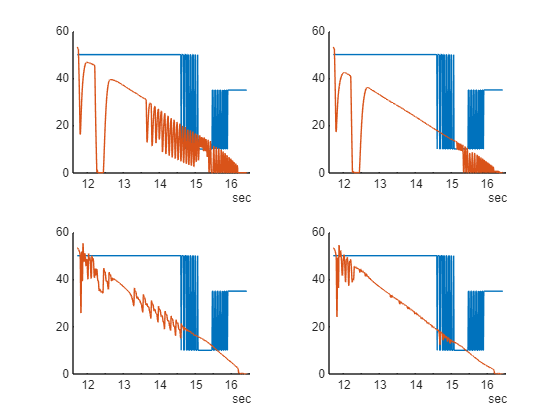

figure;
tiledlayout(2, 2);

si = experience.SimulationInfo(1);
tt = timeseries2timetable(si.logsout.getElement("FuzzingAction").Values.FuzzingOffset);

nexttile;
hold on;
plot(tt.Time, tt{:,1}(:,1));
plot(o.Time, o{:,1}(:,1));
hold off;
nexttile;
hold on;
plot(tt.Time, tt{:,1}(:,2));
plot(o.Time, o{:,1}(:,2));
hold off;

nexttile;
hold on;
plot(tt.Time, tt{:,1}(:,3));
plot(o.Time, o{:,1}(:,3));
hold off;

nexttile;
hold on;
plot(tt.Time, tt{:,1}(:,4));
plot(o.Time, o{:,1}(:,4));
hold off;

### Conclusion

The preparation of the test environment found a test execution setup in which the system under test performs significantly worst than the baseline operation. The test environment contains an RL agent which is trained by consecutive execution of the test maneouvre. During each maneouvre the agent injects noise and evaluate its effect, after the maneouvre refines its strategy in order to find the optimal test execution setup.

The emphasis is on its automatic behaviour. It finds the most problematic operation of the system under test without the active guidance of the tester. Mixing noise to the true signal samples most likely ensure that the basic operation of the controller is preserved, allowing a more subtle analysis of operation.

The trained agent can be reused in the test environment

- for model-in-the-loop (MIL) testing in which the controller model is directly taken from the ECU code, or the source Matlab/Simulink control model

- for software-in-the-loop (SIL) testing in which the whole ECU code is used

- for HIL testing in which a the real-time simulation environment encapsulate a physical ECU